# Business Analytics - Homework

## Autore: Luca Laiolo, 338344

Lo scopo dell'homework era sviluppare una libreria orientata agli oggetti per la **simulazione a eventi discreti**.

La libreria è principalmente composta da 5 classi, ovvero:

- `SimulationEngine`

- `event`

- `state`

- `futureEventsList`

- `statsManager`

addpath("MATDES\")
addpath("MATDES\Statistics\")
addpath("Esempio Benzinaio\")

La logica dietro la simulazione a eventi discreti può essere riassunta nella figura sottostante, presa da [1]. 

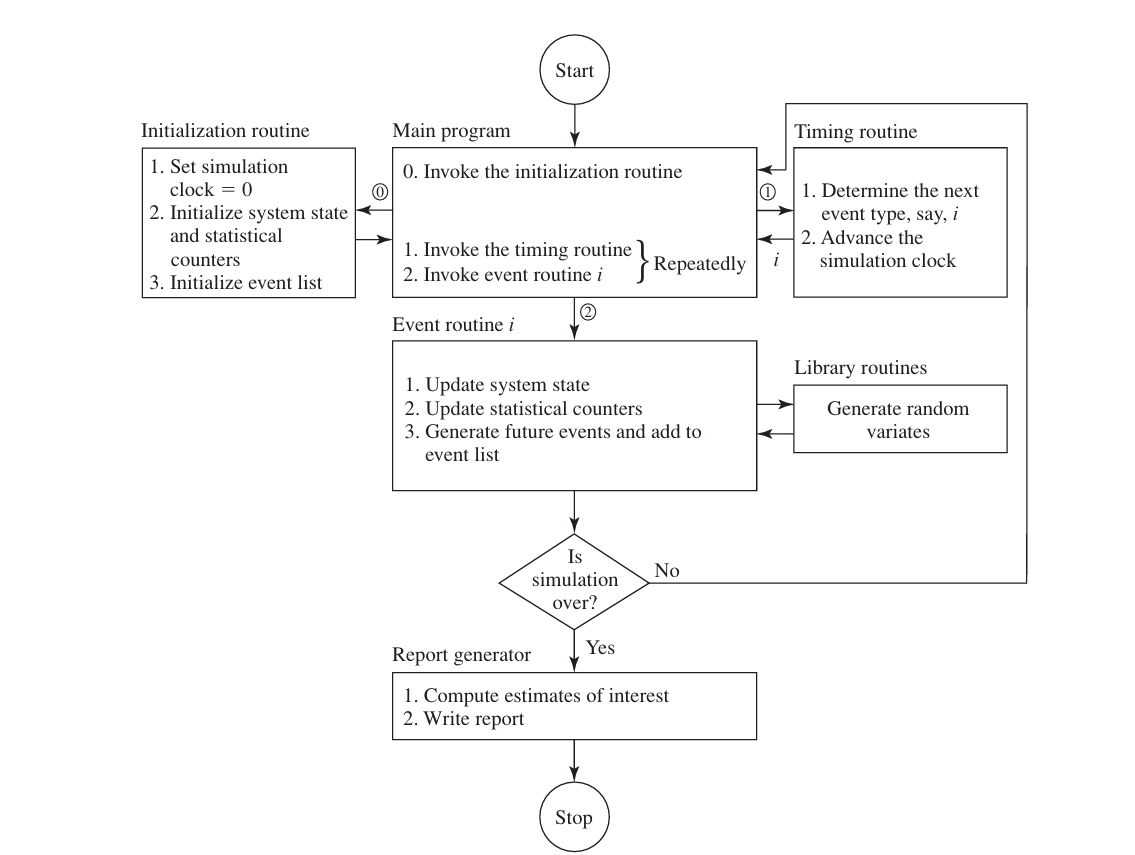

`SimulationEngine`

La classe `SimulationEngine` (sottoclasse di `handle`) definisce un framework per la simulazione a eventi discreti. In particolare, le simulazioni che eseguiremo saranno istanze di questa classe.

Le proprietà di questa classe sono le seguenti: 

- `state`, un oggetto di tipo `state`. Questo rappresenterà lo stato del sistema che vogliamo simulare; 

- `clock`, il clock di simulazione;

- `eventsList`, un oggetto di tipo `futureEventsList`. Esso conterrà gli eventi futuri schedulati;

- `stats`, un oggetto di tipo `statsManager`. Esso verrà usato per raccogliere le statistiche desiderate.

Il costruttore di questa classe si basa sui costruttori di `state, futureEventsList` e `statsManager`. La sintassi è la seguente:

Lo stato viene inizializzato utilizzando l'argomento `stateStruct`. Invece, `stats` (che è un'istanza della classe s`tatsManager`) viene inizializzato utilizzando `statStruct.` L'idea è quella di tracciare alcune quantità specificate in `statStruct`. In particolare, i nomi dei campi corrisponderanno alle quantità che vogliamo monitorare e il valore associato sarà una sottoclasse della classe `Statistic` (maggiori dettagli più avanti).

I metodi (oltre al costruttore) forniti da questa classe sono i seguenti:

- `initEventsList`, che inizializza la proprietà `eventsList`. In particolare, questo metodo riceve in input un array di oggetti di tipo `event`. Tale metodo **deve** essere chiamato **prima** di avviare l’esecuzione della simulazione. Se non viene fatto, la simulazione partirà con una `eventsList` vuota e si verificherà un errore;

- `terminationCondition`, che restituisce un flag che indica se la simulazione deve terminare o meno. Questo metodo è astratto (poiché diverse simulazioni possono avere condizioni di arresto molto diverse) e prende in input `stoppingParameters`, utili per definire condizioni che dipendono da specifici parametri;

- `run`, che esegue la simulazione. Questo metodo prende come unico argomento `stoppingParameters;`

- `clear`, che resetta lo stato, i contatori statistici e riporta a zero il clock di simulazione. Nello specifico, questo metodo prende in input `DataStruct`, un oggetto `struct` usato per aggiornare lo stato al valore default desiderato (che dipende, in generale, dalla specifica simulazione);

- `generateReport`, che stampa un sommario delle statistiche raccolte durante la simulazione.

#### `event`

La classe `event` è il cuore della simulazione a eventi discreti. Essa è una sottoclasse di `handle` e `matlab.mixin.Heterogeneous`. Dalla documentazione, "`matlab.mixin.Heterogeneous` *is an abstract class that supports forming heterogeneous arrays. A heterogeneous array is an array of objects that differ in their specific class, but are all derived from or are instances of a root class. The root class derives directly from* `matlab.mixin.Heterogeneous``"`. La motivazione dietro questa scelta è molto semplice: vorremmo costruire array eterogenei di specifici eventi che sono sottoclassi della classe `event`.

Le proprietà della classe sono le seguenti:

- `label`, una stringa che rappresenta il tipo di evento che stiamo simulando (può anche essere una stringa casuale, il codice non guarderà mai tale proprietà);

- `parameters`, che è (tipicamente) un vettore riga (o colonna) contenente i parametri necessari alla generazione di variabili aleatorie;

- `clock`, il clock dell'evento.

Il costruttore per questa classe è quello ovvio, in cui vengono assegnati i valori desiderati agli attributi della classe.

Per quanto riguarda i metodi, vengono definiti solo metodi astratti. Nello specifico, i metodi definiti sono:

- `rnd`, che restituisce un valore casuale da una qualche distribuzione usando i parametri definiti in `parameters;`

- `manageEvent`, che prende in input un oggetto di tipo `SimulationEngine` e lo aggiorna.

Per effettuare una specifica simulazione, dovremo definire questi due metodi per ogni tipo di evento che si verifica.

`state`

La classe `state` rappresenta lo stato del sistema che stiamo simulando. Essa è definita come sottoclasse della classe `dynamicprops`, che a sua volta è una sottoclasse di `handle`. La ragione dietro a questa scelta è semplice: vogliamo definire le proprietà della classe quando costruiamo davvero l'oggetto. In particolare, con la seguente sintassi

inizializziamo un oggetto di tipo `state` le cui proprietà e i valori corrispondenti corrispondono a quelli definiti in `DataStruct`. 

Oltre al costruttore, questa classe fornisce solo un altro metodo, `update`. Questo metodo prende in input due cell arrays, che corrispondono alle proprietà che vogliamo aggiornare e ai corrispondenti nuovi valori. Questo metodo può anche essere usato per ripulire lo stato.

Per esempio,

DataStruct = struct( ...
    'A', zeros(10,10), ...
    'B', zeros(10,1), ...
    'C', 0);
s = state(DataStruct)

s =   state with properties:

    B: [10×1 double]
    A: [10×10 double]
    C: 0


`futureEventsList`

La classe `futureEventsList` è una sottoclasse di `handle` e implementa una coda con priorità per gestire un array di oggetti di tipo `event` (in realtà, sottoclassi della classe `event`). La coda con priorità è implementata usando un heap binario. Questo permette alle operazioni `Enqueue` e `Dequeue` di essere effettuate con una complessità di $\mathcal{O}(logn)$, dove $n
$ è il numero di elementi all'interno dell'heap. L'implementazione corrisponde esattamente a quella presentata in [2].

I metodi forniti da questa classe non sono diversi da quelli tipici di una coda con priorità (ovvero, `Enqueue`, `Dequeue`, `First`, `Empty`). La priorità di un evento è semplicemente il suo clock di simulazione. Non vengono considerati criteri ulteriori nel caso di due eventi con lo stesso clock.

*Disclaimer. *Per la gestione della memoria, mi sono affidato alla gestione "nativa" di MATLAB (cioè, ho scritto qualcosa del tipo `v(end+1) = w` senza pensarci su troppo). Forse non è il massimo. 

`statsManager`

La classe `statsManager` è una sottoclasse di `handle` responsabile di raccogliere alcune statistiche durante la simulazione.

Le proprietà sono le seguenti:

- `statistics`, uno `struct` i cui campi corrispondono alle quantità che stiamo tracciando e i cui valori corrispondondenti sono sottoclassi della classe `Statistic`. La classe `Statistic` è una classe astratta senza proprietà pre-definite e con tre metodi astratti: `update`, `clear` e `getResult`. Questa scelta è dovuta alla volontà di rendere l'implementazione il più modulare possibile. Infatti, le statistiche che potremmo voler raccogliere possono essere di natura molto varia. Alcune possibili sottoclassi sono già state implementate, come `CountStatistic`, `SumStatistic`, `AverageStatistic`, `TimeAverageStatistic;`

- `clock`, il clock di simulazione.

Il costruttore di questa classe è abbastanza semplice. Con questa sintassi,

stiamo creando un oggetto di tipo `statsManager` il cui attributo `statistics` è initializzato usando `statStruct`. Per esempio,

statStruct = struct( ...
    'numInQueue', SumStatistic, ...
    'average_queue_length', TimeAverageStatistic);
myStatsManager = statsManager(statStruct)

myStatsManager =   statsManager with properties:

    statistics: [1×1 struct]
         clock: 0


myStatsManager.statistics

ans = struct with fields:
              numInQueue: [1×1 SumStatistic]
    average_queue_length: [1×1 TimeAverageStatistic]


myStatsManager.statistics.average_queue_length

ans =   TimeAverageStatistic with properties:

       weightedSum: 0
         totalTime: 0
    lastUpdateTime: 0


Oltre al costruttore, solo altri due metodi vengono forniti: `update` e `clear`. Entrambi i metodi si basano sui corrispettivi metodi delle sottoclassi di `Statistic`.

Per esempio,

myStatsManager.update('numInQueue', 10);
myStatsManager.statistics.numInQueue

ans =   SumStatistic with properties:

    sum: 10


myStatsManager.clock = 10;
myStatsManager.update('average_queue_length', 5);
myStatsManager.statistics.average_queue_length

ans =   TimeAverageStatistic with properties:

       weightedSum: 50
         totalTime: 10
    lastUpdateTime: 10


myStatsManager.clock = 20;
myStatsManager.update('average_queue_length', 10);
myStatsManager.statistics.average_queue_length

ans =   TimeAverageStatistic with properties:

       weightedSum: 150
         totalTime: 20
    lastUpdateTime: 20


myStatsManager.statistics.average_queue_length.getResult

ans = 7.5000

**Importante:** quando aggiorniamo un oggetto di tipo `TimeAverageStatistic`, è necessario fornire in input il **valore vecchio**, non quello nuovo.

myStatsManager.clear()
myStatsManager.statistics.numInQueue

ans =   SumStatistic with properties:

    sum: 0


myStatsManager.statistics.average_queue_length

ans =   TimeAverageStatistic with properties:

       weightedSum: 0
         totalTime: 0
    lastUpdateTime: 0


#### Esempio del benzinaio presentato a lezione

Il layout del benzinaio non è efficiente. Ci sono 4 pompe (A,B,C,D), ma non sono in parallelo. Chi possiede un'automobile con bocchetta a destra tende a preferire le pompe A o B (C o D nel caso di bocchetta a sinistra). Supponiamo che gli automobilisti abbiano preferenze rigide, per cui può accadere che le pompe A e B siano entrambe occupate, e le C e D libere, nel caso di un automobilista che ha la bocchetta a destra e blocca l'accesso. Gli spazi in coda sono limitati, e quando sono tutti occupati, un eventuale auto in arrivo non può mettersi in coda.

Dopo aver fatto benzina, si va a pagare alla cassa, occupando lo spazio davanti alla pompa. Può accadere che un automobilista che ha pagato debba aspettare in posizione A che si liberi lo spazio B per uscire (cosa che accade se un automobilista lo occupa mentre fa benzina o paga alla cassa).

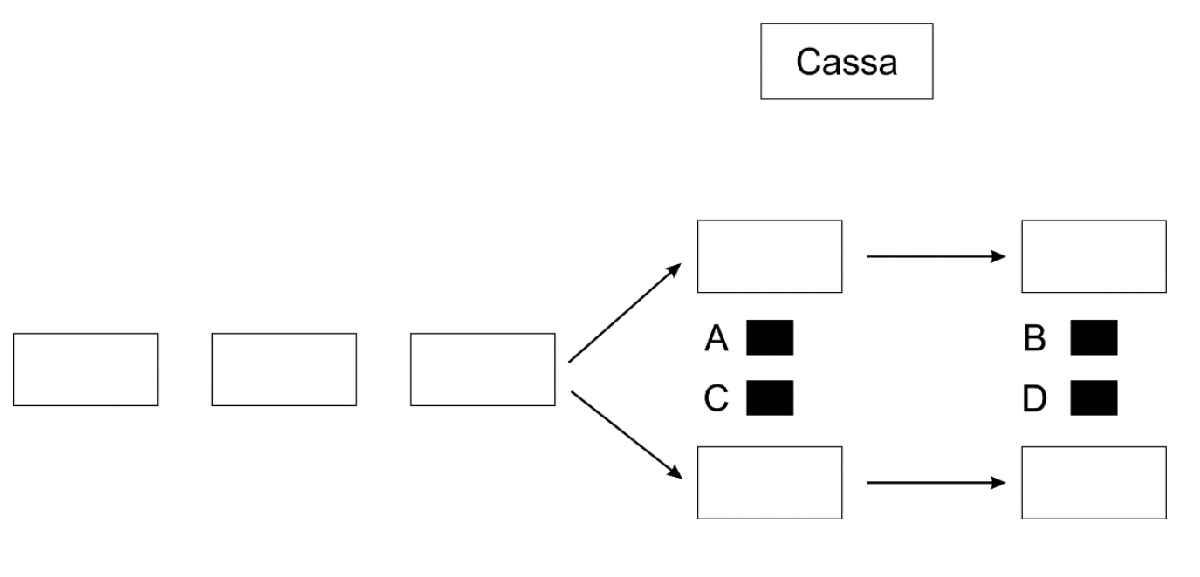

Si vogliono raccogliere statistiche sull'utilizzo delle pompe e del cassiere, lunghezza media della coda, numero di clienti che non possono mettersi in coda, etc. Una questione rilevante è se sarebbe utile mettere due persone alla cassa.

Gli eventi da modellare sono 3: l'arrivo di un auto al benzinaio, la fine di un rifornimento e l'uscita dalla cassa (che è una coda M/M/1). Supponiamo che la fine del rifornimento e l'arrivo in coda alla cassa coincidano. Supponiamo inoltre che immediatamente dopo aver pagato l'automobilista (e l'auto) escano dal sistema, liberando così un posto. Nel mondo vero chiaramente non è così. Specialmente, è molto improbabile che non appena l'automobilista finisce di pagare lasci il sistema e si liberi un posto. Si potrebbe introdurre un evento `Chatting` al fine di modellare il tempo perso dall'automobilista in chiacchiere alla cassa. Una maniera più intelligente di introdurre nel sistema un fenomento di questo tipo consiste semplicemente nell'aumentare i tempi di servizio alla cassa. Facciamo inoltre tre assunzioni, più verosimili. La prima è che gli automobilisti scelgano sempre di andare a pagare alla cassa con meno persone in coda. La seconda riguarda il comportamento degli automobilisti quando entrano a fare benzina. Essi infatti scelgono sempre il posto disponibile più lontano dall'entrata. Ad esempio, se arriva un automobilista con la bocchetta a destra e se sia i posti A che B sono liberi, esso si posizionerà in B. L'ultima assunzione che facciamo riguarda il comportamento degli automobilisti alla fine del pagamento alla cassa. Supponiamo che ci siano 3 pompe di benzina per lato (ad esempio, A, B, C a sinistra e D, E, F a destra) e che un auto che occupa la posizione B abbia finito di pagare. L'auto però non può uscire perchè un altro automobilista che ha occupato la posizione C non ha ancora finito di pagare. Nella simulazione si assume che, quando l'automobilista in C finisce di pagare, istantaneamente entrambi gli automobilisti B e C lasciano il sistema, liberando i loro posti.

Nel sistema ci sono essenzialmente due code: quella per entrare a fare benzina e quella per pagare alla cassa. Tuttavia, queste code sono in un certo senso diverse da quelle viste a lezione. Per esempio, per modellare la coda alla cassa non basta dire che `numInQueue = n`, ma è necessario modellare anche *chi* è in coda. Se non facessimo così, non sapremmo poi quale posto verrebbe liberato al termine del pagamento. Discorso simile per la coda per fare benzina. Non è sufficiente tenere traccia della lunghezza della coda ma bisogna tenere traccia di dove si trova la bocchetta di ogni auto.

Il codice seguente simula il sistema `numReps` volte. Si suppone che l'orizzonte di tempo da simulare sia 10000 minuti (circa 7 giorni). Supponiamo che il processo stocastico degli arrivi sia descritto da un processo di Poisson di rate 1/2 (quindi, i tempi di inter-arrivo sono esponenziali di media 2 minuti). Supponiamo che i tempi necessari per il rifornimento e il pagamento alla cassa siano entrambi uniformi, per ogni pompa di benzina e per ogni servitore.

Il codice permette di simulare un sistema con più servitori, con più di sole due strade in cui incanalarsi per fare benzina (forse non ha troppo senso in questo caso) e più di sole due pompe per strada (in altre parole, se `nSpots = 3` e `nLanes = 2`, il layout del sistema è qualcosa del tipo A - B - C / D - E - F). Supponiamo inoltre che esista una lunghezza massima della coda per entrare a fare benzina. Se arriva un'auto e la lunghezza della coda è superiore a `maxFuelQueueLength` perdiamo il cliente.

Gli intervalli di confidenza vengono calcolati a partire da simulazioni indipendenti (aventi stessa condizione iniziale) usando la funzione `normfit`.

numReps = 50;
nLanes = 2;
params = struct( ...
    'maxFuelQueueLength', 6, ...
    'numServer', 2, ...
    'arrivalRate', 1/2, ...
    'lb_server', 2, ...
    'ub_server', 5, ...
    'lb_refuel', 3, ...
    'ub_refuel', 8, ...
    'nLanes', nLanes, ...
    'nSpots', 5, ...
    'laneDist', makedist('Multinomial', 'probabilities', ones(nLanes, 1)/nLanes), ...
    'numReps', numReps, ...
    'duration', 10000);

[numLostCI, averageFuelQueueLengthCI, averageServerQueueLengthCI, ...
    averageServerIdlenessCI, averagePumpUsageCI] = runBenzinaio(params);

Running repetition 1/50...
Running repetition 2/50...
Running repetition 3/50...
Running repetition 4/50...
Running repetition 5/50...
Running repetition 6/50...
Running repetition 7/50...
Running repetition 8/50...
Running repetition 9/50...
Running repetition 10/50...
Running repetition 11/50...
Running repetition 12/50...
Running repetition 13/50...
Running repetition 14/50...
Running repetition 15/50...
Running repetition 16/50...
Running repetition 17/50...
Running repetition 18/50...
Running repetition 19/50...
Running repetition 20/50...
Running repetition 21/50...
Running repetition 22/50...
Running repetition 23/50...
Running repetition 24/50...
Running repetition 25/50...
Running repetition 26/50...
Running repetition 27/50...
Running repetition 28/50...
Running repetition 29/50...
Running repetition 30/50...
Running repetition 31/50...
Running repetition 32/50...
Running repetition 33/50...
Running repetition 34/50...
Running repetition 35/50...
Running repetition 36/50...
R


disp('95% normal confidence intervals: ');

95% normal confidence intervals: 


fprintf( 'CI for number of lost customers: [%.2f, %.2f]\n', numLostCI);

CI for number of lost customers: [880.58, 909.02]


fprintf( 'CI for average fuel queue length: [%.2f, %.2f]\n', averageFuelQueueLengthCI);

CI for average fuel queue length: [2.34, 2.37]


for i=1:params.numServer
    fprintf('CI for average server %d queue length: ', i)
    fprintf('[%.2f, %.2f]\n', averageServerQueueLengthCI(:, i))
    fprintf('\n')
end

CI for average server 1 queue length: 

[1.44, 1.45]


CI for average server 2 queue length: 

[1.03, 1.04]


for i=1:params.numServer
    fprintf('CI for average server %d idleness: ', i)
    fprintf('[%.2f, %.2f]\n', averageServerIdlenessCI(:, i))
    fprintf('\n')
end

CI for average server 1 idleness: 

[0.21, 0.21]


CI for average server 2 idleness: 

[0.35, 0.36]


dim = size(averagePumpUsageCI);
nRows = dim(1);           
nCols = dim(2);
lb = averagePumpUsageCI(1,:);
ub  = averagePumpUsageCI(2,:);
nColsFinal = numel(lb)/params.nLanes;
for i = 1:params.nLanes

    elems = arrayfun(@(k) sprintf('[%.5f, %.5f]', ...
        lb((k-1)*params.nLanes + i), ub((k-1)*params.nLanes + i)), ...
        1:nColsFinal, ...
        'UniformOutput', false);

    rowStr = ['[ ' strjoin(elems, ' ') ' ]'];

    if i==1
        disp('CI for average pump usage: ')
    end
    disp(rowStr);
end

CI for average pump usage: 


[ [0.18334, 0.18718] [0.20481, 0.20869] [0.22584, 0.22884] [0.24631, 0.24910] [0.26076, 0.26273] ]
[ [0.18195, 0.18573] [0.20456, 0.20798] [0.22457, 0.22798] [0.24540, 0.24809] [0.26153, 0.26375] ]


A prima vista può sembrare strano che la lunghezza media della coda alla cassa 1 sia maggiore della lunghezza media della coda alla cassa 2. Questo è dovuto al fatto che, a parità di lunghezza, si preferisce sempre la cassa 1 alla cassa 2 (il motivo è banalmente che nel codice si cerca l'indice della cassa con la lunghezza della coda minima e la funzione `min` restituisce soltanto il primo degli eventuali molteplici indici).

Non sorprende neanche l'utilizzo medio delle pompe di benzina: quelle più vicine all'uscita sono quelle più utilizzate. Questo è dovuto al fatto che quando un automobilista entra a fare benzina, esso va a occupare il posto più lontanto dall'entrata, al fine massimizzare il numero di clienti che effettivamente entrano nel sistema.

Guardando solamente le statistiche, non si può dire quale sia la scelta ottimale del numero di servitori. Per decidere, avremmo bisogno di qualche indicatore economico.

#### References

[1] Averill M. Law and David M. Kelton. *Simulation Modeling and Analysis*. McGraw-Hill Higher Education, 5th edition, 2015. 

[2] P. Crescenzi et al., *Strutture di dati e algoritmi. Progettazione, analisi e visualizzazione*. Pearson, 2012